# Welcome to

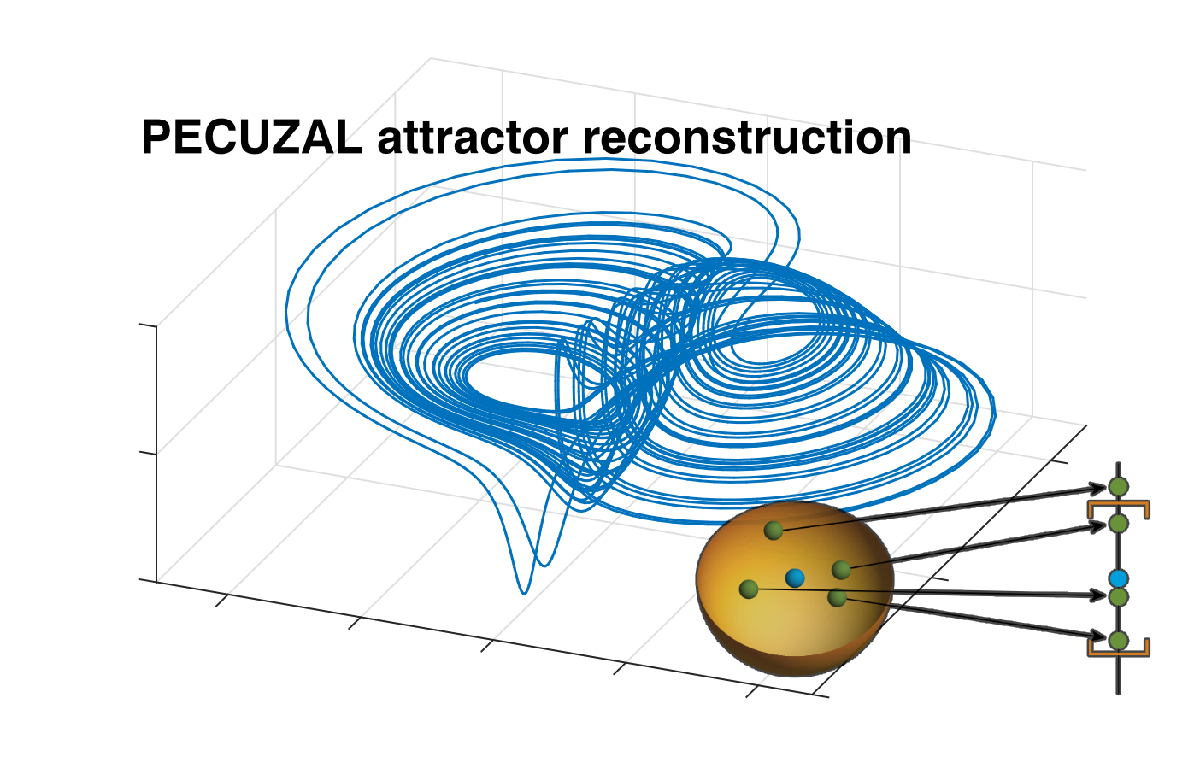

We introduce the PECUZAL automatic embedding of time series method for Matlab. It is solely basedon the paper [Kraemer et al. 2020](https://arxiv.org/abs/2011.07040) (Open Source), where the functionality is explained in detail. Here we give an introduction to its easy usage in three examples. Enjoy Embedding! 

### Installation

The method is available as a Toolbox. Simply double-click the ... [...]. The Toolbox is also available on Matlab Central [...]

[add png's for illustration]

### Citing and reference

If you enjoy this tool and find it valuable for your research please cite

**Kraemer et al., "A unified and automated approach to attractor reconstruction",  **[**arXiv:2011.07040 [physics.data-an] **](https://arxiv.org/abs/2011.07040)**, 2020.**

or as BiBTeX-entry:

@misc{kraemer2020,

    title={A unified and automated approach to attractor reconstruction}, 

    author={K. H. Kraemer and G. Datseris and J. Kurths and I. Z. Kiss and J. L. Ocampo-Espindola and N. Marwan},    

    year={2020},

    eprint={2011.07040},

    archivePrefix={arXiv},

    primaryClass={physics.data-an}

    url={https://arxiv.org/abs/2011.07040}

    }

### Basic usage: Three examples

Let us first take a look at the docstring of `pecuzal_embedding`-function, by typing

help pecuzal_embedding

  pecuzal_embedding is a fully automated phase space reconstruction method
  based on the ideas of Pecora et al., Chaos 17 (2007) & Uzal et al., Phys.
  Rev. E (2011).
 
  Minimum input-arguments: 1
  Maximum input-arguments: 21
 
  [Y, tau_vals, ts_vals, epsilon_mins, Ls] = 
                        pecuzal_embedding(x, taus [,Name, Value]);
 
  This function embeds the input time series `x` with different delay
  times tau. `x` can be a multivariate dataset, i.e. many univariate time 
  series in one matrix. The approach views the problem of choosing all 
  embedding parameters as being one and the same problem addressable using 
  a single statistical test formulated directly from the reconstruction 
  theorems. 
  In combination with the L-statistic, a cost-function, which evaluates the
  goodness of a reconstruction, this allows for varying time delays 
  appropriate to the data and simultaneously helps decide on embedding 
  dimension. 
 
  Input:

As you can see, there are several optional parameters as (Name, Value)-pairs, which you can play around with. We recommend to stick to the Default values first, as described in [kraemer2020], and only parse an adequate Theiler-window, in order to exclude serially correlated time series values from the nearest neighbour search. We will see in the following how that could be done.

#### Univariate example (Rössler system)

We exemplify the proposed embedding method by embedding the `y`-component of the Roessler system with standard parameters 

clear, clc
% set parameters for standard Rössler
a = 0.2;
b = 0.2;
c = 5.7;
% Set time series length and sampling
N = 5000;
dt = 0.2;
transient_time = 2500;
tf = (N+transient_time)* dt; 
t = 0:dt:tf;

Let us first defne the [Rössler ODE-System](https://en.wikipedia.org/wiki/R%C3%B6ssler_attractor) and solve it to obtain the time series..

% the roessler ODE
roe = @(t,x) [-x(2)-x(3); x(1)+a*x(2); b+x(3)*(x(1)-c)];  % Rossler system

% solve the ODE
x0 = [1.; .5; 0.5]; % define initial conditions  
SOL = ode45(roe,[t(1) t(end)],x0); % solve ODE
data = deval(SOL,t);

% Store sampled time series    
data = data(:,2501:end-1)';
t = t(1:end-2501);

We focus on the y-component and compute auto mutual information (MI), in order to estimate an appropriate Theiler window. This is especially important when dealing with highly sampled datasets. Let us also plot the data and the MI.

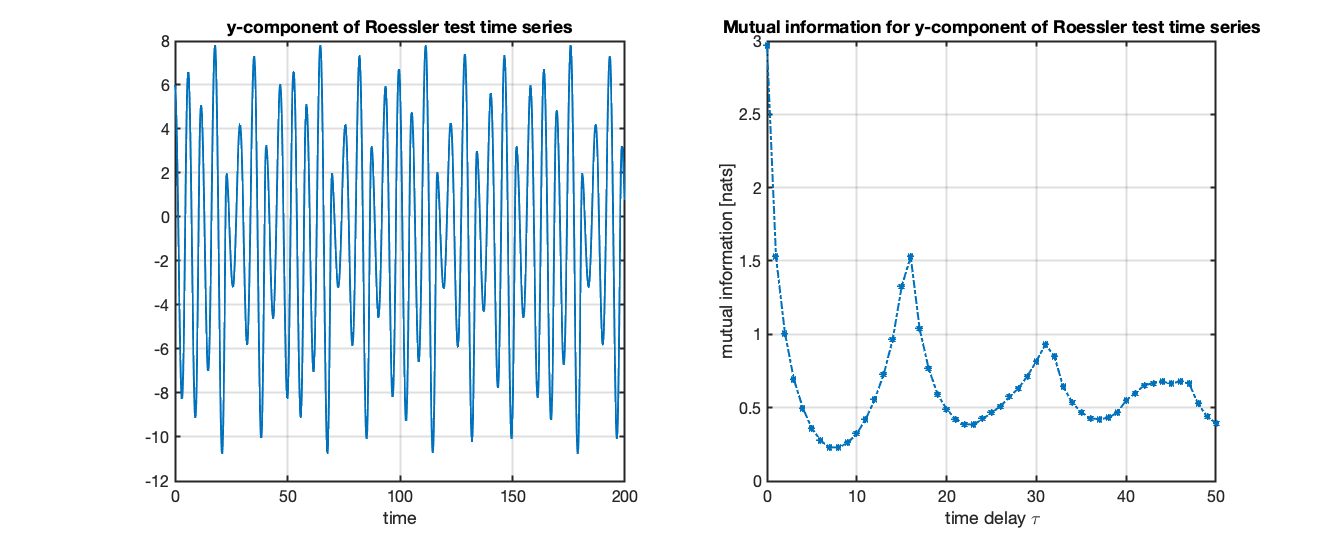

y = data(:,2);  % bind y-component
mi = mutualinformation(y,50); % compute MI

figure('Units','normalized','Position',[.3 .3 .7 .5])

subplot(1,2,1)
plot(t(1:1000), y(1:1000), 'LineWidth',2)
title('y-component of Roessler test time series')
xlabel('time')
set(gca,'LineWidth',2)
set(gca,'FontSize',16)
grid on

subplot(1,2,2)
plot(mi(:,1), mi(:,2),'-.*','LineWidth',2)
xlabel('time delay \tau')
ylabel('mutual information [nats]')
title('Mutual information for y-component of Roessler test time series')
set(gca,'LineWidth',2)
set(gca,'FontSize',16)
grid on

Now we are ready to go and simply call the PECUZAL algorithm `pecuzal_embedding.m` with a Theiler window determined from the first minimum of the mutual information shown in the above Figure, i.e. `theiler`=7, and possible delays ranging from `0:100`. 

**NOTE: The following computation will take approximately 2-3 minutes (depending on the machine you are running the code on).**

[Y_reconstruct, tau_vals, ts_vals, Ls, eps] = pecuzal_embedding(y, 0:100, 'theiler', 7)

Algorithm stopped due to minimum L-value reached. VALID embedding achieved.


Y_reconstruct =     5.9971    0.0132   -8.2602
    5.7856   -1.4035   -8.2342
    5.3290   -2.8216   -7.8740
    4.6361   -4.1834   -7.1814
    3.7255   -5.4313   -6.1721
    2.6255   -6.5100   -4.8768
    1.3732   -7.3687   -3.3416
    0.0132   -7.9637   -1.6297
   -1.4035   -8.2602    0.1726
   -2.8216   -8.2342    1.9499


tau_vals =      0     7    15


ts_vals =      1     1     1


Ls =    -2.5086   -3.2208   -3.1632


eps = 1×3 cell array
    {101×1 double}    {101×1 double}    {101×1 double}


Elapsed time is 138.654272 seconds.


which, after the computation has finished, leads to the following note in the console:

*                                            Algorithm stopped due to minimum L-value reached. VALID embedding achieved.*

`Y_reconstruct` stores the reconstructed trajectory. Since in this example `Y_reconstruct` is a three-dimensional

trajectory we can actually plot it, in order to visualize the result.

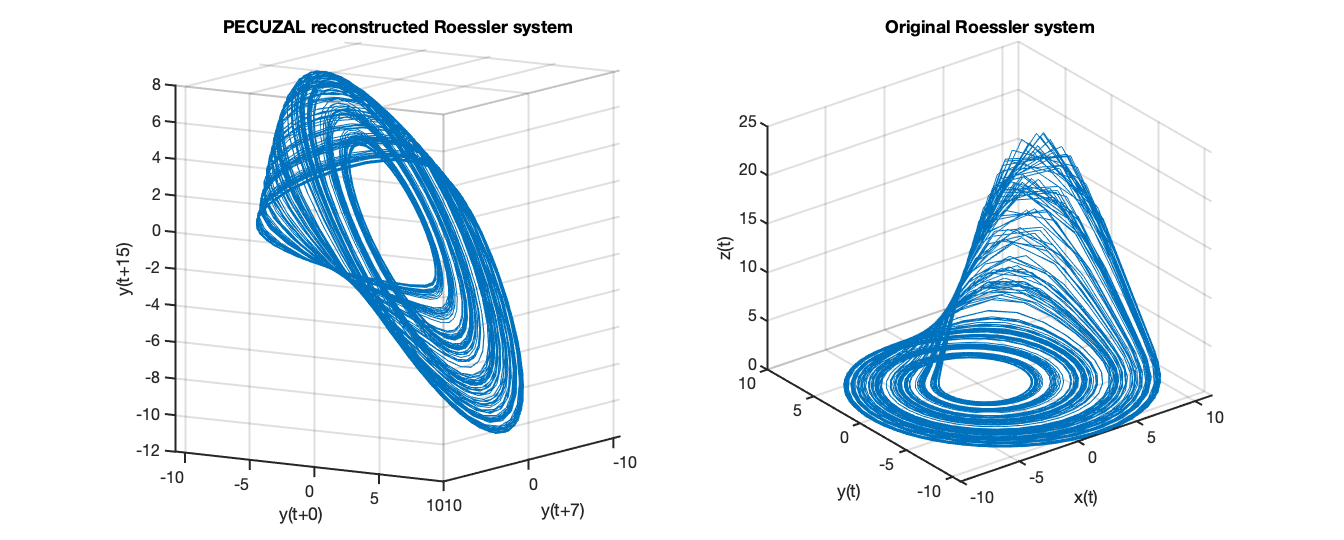

figure('Units','normalized','Position',[.3 .3 .7 .5])

subplot(1,2,1)
plot3(Y_reconstruct(:,1), Y_reconstruct(:,2), Y_reconstruct(:,3))
xlabel(strcat('y(t+',num2str(tau_vals(1)),')'))
ylabel(strcat('y(t+',num2str(tau_vals(2)),')'))
zlabel(strcat('y(t+',num2str(tau_vals(3)),')'))
title('PECUZAL reconstructed Roessler system')
set(gca,'LineWidth',2)
set(gca,'FontSize',16)
grid on

subplot(1,2,2)
plot3(data(:,1), data(:,2), data(:,3))
xlabel('x(t)')
ylabel('y(t)')
zlabel('z(t)')
title('Original Roessler system')
set(gca,'LineWidth',2)
set(gca,'FontSize',16)
grid on

For the correct axis labels we used the delay values the PECUZAL algorithm used and which are stored in the output-variable we named `tau_vals` above. 

This means, that the reconstructed trajectory consists of the unlagged time series (here the `y`-component) and two more components with the time series lagged by 7 and 15 sample, respectively. Note the coincidence with the first minimum of the mutual information... The output variable `ts_vals` stores the chosen time series for each delay value stored in `tau_vals`.  Since there is only one time series we fed in, it is simply

ts_vals

ts_vals =      1     1     1


This output is only needed for the multivariate case, see section Multivariate example (Rössler system) . We can also look at the output of the low-level function, namely the `continuity-statistic`, which led to the result. We stored these statistics for each embedding cycle in the variable `eps`.

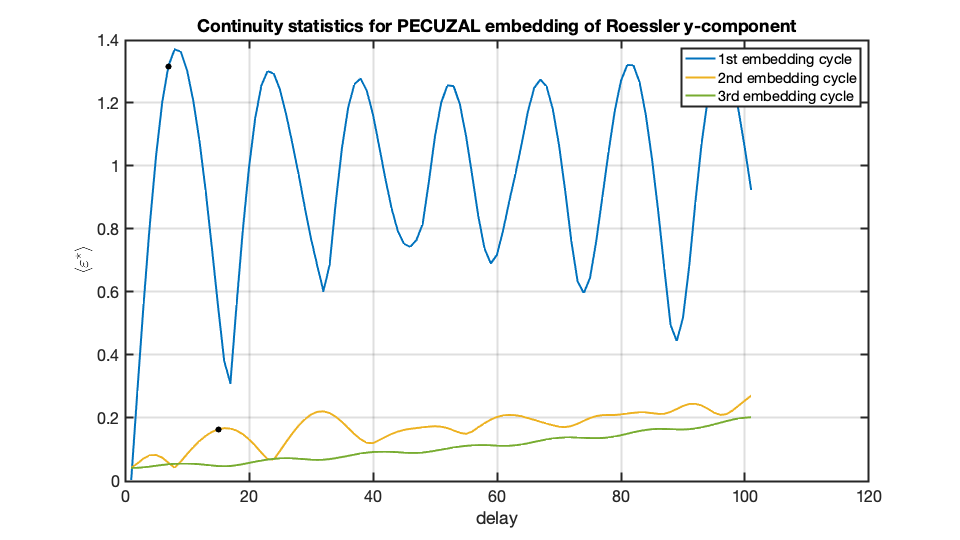

figure('Units','normalized','Position',[.3 .3 .5 .5])
plot(eps{1}(:,1),'LineWidth',2), hold on
scatter(tau_vals(2)+1, eps{1}(tau_vals(2),1), 40, 'k', 'filled', "HandleVisibility","off"), hold on
plot(eps{2}(:,1),'LineWidth',2), hold on
scatter(tau_vals(3)+1, eps{2}(tau_vals(3),1), 40, 'k', 'filled', "HandleVisibility","off"), hold on
plot(eps{3}(:,1),'LineWidth',2), hold on
legend('1st embedding cycle','2nd embedding cycle','3rd embedding cycle')
title('Continuity statistics for PECUZAL embedding of Roessler y-component')
xlabel('delay')
ylabel('$\langle \varepsilon^\star \rangle$','Interpreter','latex')
set(gca,'LineWidth',2)
set(gca,'FontSize',16)
grid on

The black markers point at the postitions, where the algorithm picked the delays for the reconstruction from. In the 3rd embedding cycle there is no delay value picked and the algorithm breaks, because it can not minimize the `L`-statistic further. Its values for each embedding cycle are stored in `Ls`:

Ls

Ls =    -2.5086   -3.2208   -3.1632


#### Multivariate example (Rössler system)

Similar to the approach in the preceeding section, we now highlight the capability of the proposed embedding method for a multivariate input. The idea is now to feed in all three time series to the algorithm, even though this is a very far-from-reality example. We already have an adequate representation of the system we want to reconstruct, namely the three time series from the numerical integration. But let us see what PECUZAL suggests for a reconstruction.

Since we have to deal with three time series now, let us estimate the Theiler window as the maximum of all Theiler windows of each time series. Again, we estimate such a Theiler window by taking the first minimum of the auto mutual information.

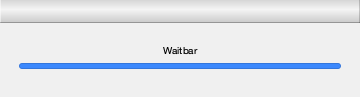

mis = zeros(length(mi),3);
for i = 1:3
    Z = mutualinformation(data(:,i),50,0);
    mis(:,i) = Z(:,2);
end

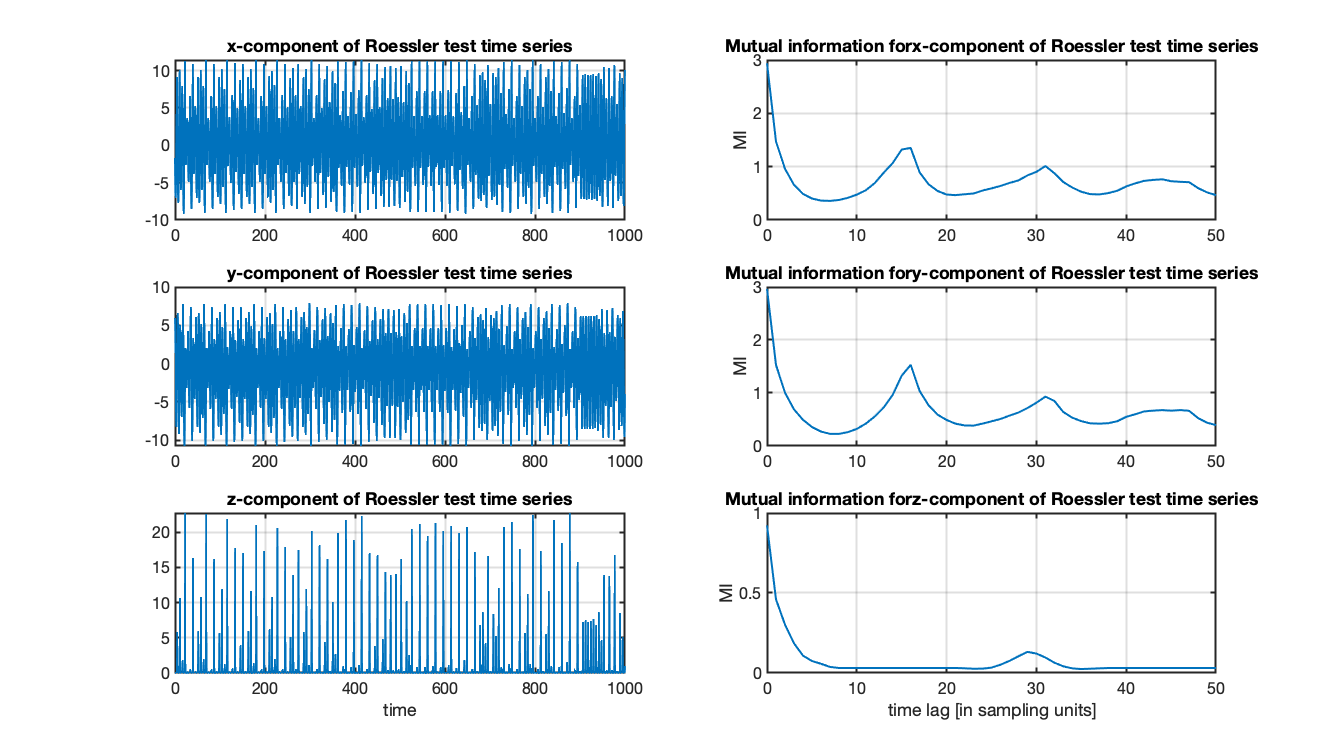

    
figure('Units','normalized','Position',[.3 .3 .7 .7])
ts_str = ['x';'y';'z'];

cnt = 1;
for i = 0:2:4
    subplot(3,2,i+1)
    plot(t,data(:,cnt), 'LineWidth', 2)
    if i == 4
        xlabel('time')
    end
    title(strcat(ts_str(cnt),'-component of Roessler test time series'))
    set(gca,'LineWidth',2)
    set(gca,'FontSize',16)
    grid on
    
    subplot(3,2,i+2)
    plot(Z(:,1),mis(:,cnt), 'LineWidth', 2)
    ylabel('MI')
    if i == 4
        xlabel('time lag [in sampling units]')
    end
    title(strcat('Mutual information for ',ts_str(cnt),'-component of Roessler test time series'))
    set(gca,'LineWidth',2)
    set(gca,'FontSize',16)
    grid on 
    
    cnt = cnt + 1; 

end

Due to the spikyness of the `z`-component the according auto mutual information yields no meaningful result here. So we stick to the choice of `theiler = 7` here and  call the PECUZAL algorithm with default optional parameters and possible delays ranging from `0:100`.

**NOTE: The following computation will take approximately 10-15 minutes (depending on the machine you are running the code on).**

[Y_reconstruct_m, tau_vals_m, ts_vals_m, Ls_m, eps_m] = pecuzal_embedding(data, 0:100, 'theiler', 7)

Algorithm stopped due to minimum L-value reached. VALID embedding achieved.


Y_reconstruct_m =    -1.6423    5.7856   -4.9555
   -2.8306    5.3290   -5.7989
   -3.9510    4.6361   -6.4403
   -4.9555    3.7255   -6.8457
   -5.7989    2.6255   -6.9889
   -6.4403    1.3732   -6.8535
   -6.8457    0.0132   -6.4338
   -6.9889   -1.4035   -5.7352
   -6.8535   -2.8216   -4.7748
   -6.4338   -4.1834   -3.5813


tau_vals_m =      0     1     3


ts_vals_m =      1     2     1


Ls_m =    -2.6813   -3.2425   -3.1780


eps_m = 1×3 cell array
    {101×3 double}    {101×3 double}    {101×3 double}


Elapsed time is 662.127816 seconds.


which, after the computation has finished, leads to the following note in the console:

*                                            Algorithm stopped due to minimum L-value reached. VALID embedding achieved.*

The suggested embedding parameters...

tau_vals_m

tau_vals_m =      0     1     3


ts_vals_m

ts_vals_m =      1     2     1


... reveal that PECUZAL builds the reconstructed trajectory `Y_reconstruct_m` from the unlagged `x`-component time series (having index `0`),  the `y`-component lagged by 1 sample, and finally again the `x`-component lagged by 3 samples. As expected the total `L`-value is smaller here than in the univariate case:

L_total_uni = min(Ls)

L_total_uni = -3.2208

L_total_multi = min(Ls_m)

L_total_multi = -3.2425

The reconstructed attractor looks also quite similar to the original one, even though that is not a proper evaluation criterion for the goodness of a reconstruction, see [kraemer2020].

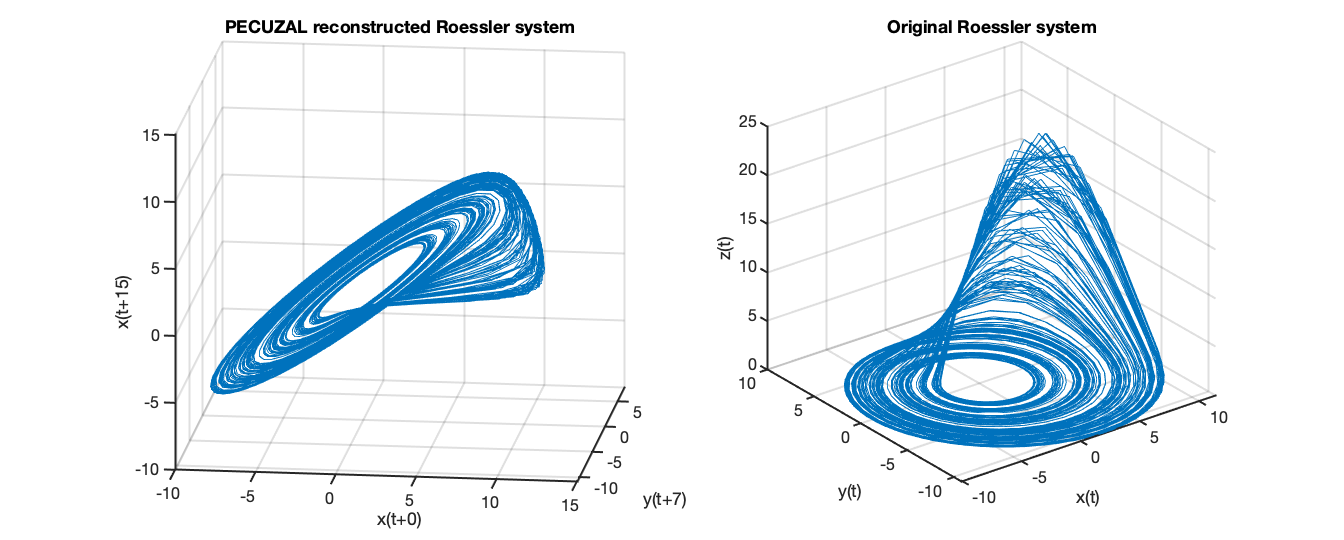

figure('Units','normalized','Position',[.3 .3 .7 .5])

subplot(1,2,1)
plot3(Y_reconstruct_m(:,1), Y_reconstruct_m(:,2), Y_reconstruct_m(:,3))
xlabel(strcat(ts_str(ts_vals_m(1)),'(t+',num2str(tau_vals(1)),')'))
ylabel(strcat(ts_str(ts_vals_m(2)),'(t+',num2str(tau_vals(2)),')'))
zlabel(strcat(ts_str(ts_vals_m(3)),'(t+',num2str(tau_vals(3)),')'))
title('PECUZAL reconstructed Roessler system')
set(gca,'LineWidth',2)
set(gca,'FontSize',16)
grid on

subplot(1,2,2)
plot3(data(:,1), data(:,2), data(:,3))
xlabel('x(t)')
ylabel('y(t)')
zlabel('z(t)')
title('Original Roessler system')
set(gca,'LineWidth',2)
set(gca,'FontSize',16)
grid on

#### Stochastic source example

Finally we demonstrate how the PECUZAL method deals with non-deterministic input data. Therefore, we create a simple AR(1)-process:

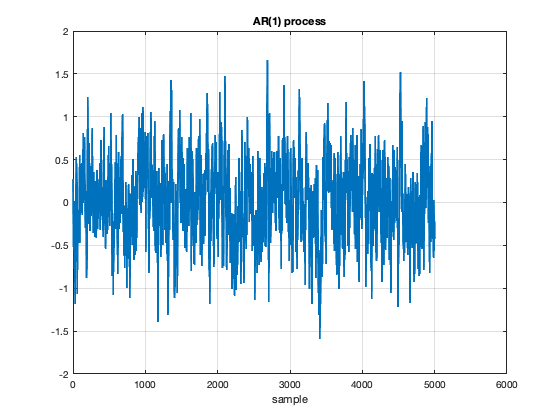

M = 2000; % length of the time series, which we want to obtain
x = zeros(1,M+10);
x(1) = .2; % intial value
alpha = .9; % auto-correlation parameter
p = .2; % noise amplitude
for i = 2:N+10
    x(i) = alpha*x(i-1) + p*randn;
end
x = x(10:end);

figure
plot(x,'LineWidth',2)
title('AR(1) process')
xlabel('sample')
grid on

When we now call the PECUZAL algorithm...

[Y_reconstruct_s, tau_vals_s, ts_vals_s, Ls_s, eps_s] = pecuzal_embedding(x)

Algorithm stopped due to non-decreasing L-value. NO valid embedding achieved.


Y_reconstruct_s =     0.1211
    0.2760
    0.1496
   -0.1263
   -0.1024
   -0.2318
   -0.5278
   -0.2959
   -0.3174
   -0.5506


tau_vals_s = 0

ts_vals_s = 1

Ls_s = -1.9702

eps_s = 1×1 cell array
    {51×1 double}


 ...we'll get the following note in the console:

*                                            Algorithm stopped due to non-decreasing L-value. NO valid embedding achieved.*

The algorithm did not obtain any valid embedding, thus, it values the input data as a non-deterministic source.